clc; clear variables; close all;

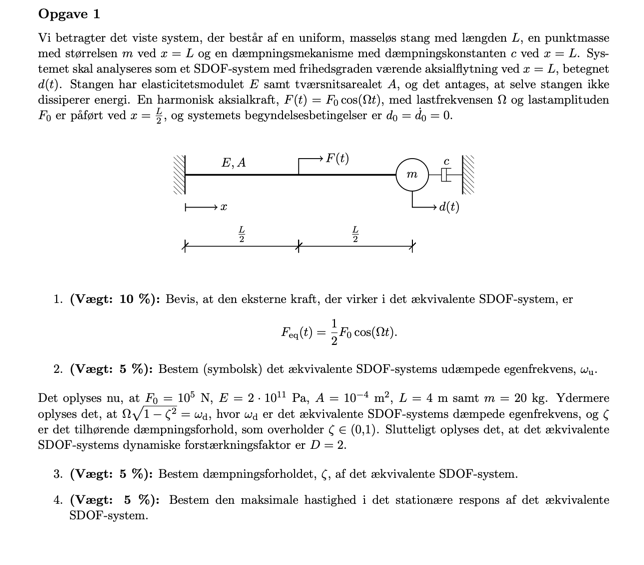

1.1 Idet vi kalder lokationen af kraften 1 og lokationen af massen 2 kan vi vha. D'Alemberts princip opskrive følgende


$$d\left(t\right)=\delta_{21} F\left(t\right)-\delta_{22} m\ddot{d} \left(t\right)-\delta_{22} c\dot{d} \left(t\right)\;\;\;\Rightarrow \;m\ddot{d} \left(t\right)+c\dot{d} \left(t\right)+\frac{1}{\delta_{22} }d\left(t\right)=\frac{\delta_{21} }{\delta_{22} }F\left(t\right)$$


Herfra ser vi at


$$F_{\mathrm{eq}} \left(t\right)=\alpha \;F\left(t\right)=\frac{\delta_{21} \;}{\delta_{22} }F\left(t\right)$$


Fra elementær statik har vi at vi ved indsættelse af en punktenhedslast får spændingen i stangen


$$\sigma =\frac{1}{A}$$


Hvilket tilsvarer en forskydning pr. enhedslængde på


$$\epsilon =\frac{\sigma }{E}=\frac{1}{A\;E}$$


Multiplicerer vi denne med lokation 1 (kraftens lokation) får vi det fleksibilitetskoefficienten $\delta_{21}$ og multiplicerer vi den med lokation 2 (massens lokation) får vi fleksibilitetskoefficienten $\delta_{22}$. Altså:


$$\delta_{21} =\epsilon \;\frac{L}{2}=\frac{L}{2\;A\;E}$$



$$\delta_{22} =\epsilon \;L=\frac{L}{A\;E}$$


Således kan vi finde $\alpha$


$$\alpha =\frac{\delta_{21} }{\delta_{22} }=\frac{\frac{L}{2\mathrm{AE}}}{\frac{L}{\mathrm{AE}}}=\frac{1}{2}$$


Altså har vi


$$F_{\mathrm{eq}} \left(t\right)=\alpha \;F\left(t\right)=\frac{1}{2}F_0 \cos \left(\Omega \;t\right)$$


1.2

Vi har fra ovenfor at 


$$k_{\mathrm{eq}} =\frac{1}{\delta_{22} }=\frac{A\;E}{L}$$


Idet den udæmpede egenfrekvens er


$$\omega_u =\sqrt{\frac{k_{\mathrm{eq}} }{m}}$$


har vi


$$\omega_u =\sqrt{\frac{A\;E}{L\;m}}$$


1.3

Vi har fra opgaven at


$$\omega_d =\Omega \;\sqrt{1-\zeta^2 }$$


Generelt har vi at 


$$\omega_d =\omega_u \sqrt{1-\zeta^2 }$$


Altså må $\omega_u = \Omega$, hvilket betyder der er resonans, $p = 1$. Idet der er resonans har vi at


$$D=\frac{1}{2\zeta }\;\;\;\Rightarrow \;\zeta =\frac{1}{2D}\;\Rightarrow \zeta =\frac{1}{4}$$


1.4 Vi har at det stationære respons er


$$d_p \left(t\right)=\frac{F_0 }{\sqrt{{\left(k-m\Omega^2 \right)}^2 +c^2 \Omega^2 }}\cos \left(\Omega t-\arctan \left(\frac{c\Omega }{k-m\Omega^2 }\right)\right)$$


For at kunne bruge denne skal vi bruge $c$, som findes fra $c=2\zeta m\omega_u$. Derudover, har vi fra tidligere at $\omega_u = \Omega = \sqrt{\frac{AE}{Lm}}$ og derfor kan udtrykket for $d_p(t)$ altså omskrives som:


$$d_p \left(t\right)=\frac{F_0 }{\sqrt{\frac{4\zeta^2 A{\;}^2 E^2 }{L^2 }}}\cos \left(\sqrt{\frac{A\;E}{L\;m}}t-\arctan \left(\frac{\frac{2\zeta \;A\;E}{L}}{0}\right)\right)=\frac{F_0 }{\sqrt{\frac{4\zeta^2 A{\;}^2 E^2 }{L^2 }}}\cos \left(\sqrt{\frac{A\;E}{L\;m}}t-\frac{\pi }{2}\right)$$


Hvilket løses i Matlab som

F_0 = 1e5; %N
F_eq = 1/2 * F_0

F_eq = 50000

zeta = 1/4;
A = 1e-4; %m^2
E = 2e11; %Pa
L = 4; %m
m = 20; %kg

syms t

dp = F_eq/(sqrt(4*zeta^2*A^2*E^2/L^2))*cos(sqrt(A*E/(L*m))*t - pi/2)

$$dp = \frac{\cos\left(500\,t-\frac{\pi }{2}\right)}{50}$$

Dette kan nu differentieres for at finde et udtryk for hastigheden:

ddp = diff(dp,t)

$$ddp = -10\,\sin\left(500\,t-\frac{\pi }{2}\right)$$

Således er vores hastighedsudtryk i den stationære respons fundet til


$$\dot{d} \left(t\right)=-10\sin \left(500t-\frac{\pi }{2}\right)\;\;\;\;\;\Rightarrow \;\;\;\max \left(\dot{d} \left(t\right)\right)=10$$


Altså er den maksimale hastighed i det stationære respons 10 m/s.

clc; clear variables; close all;

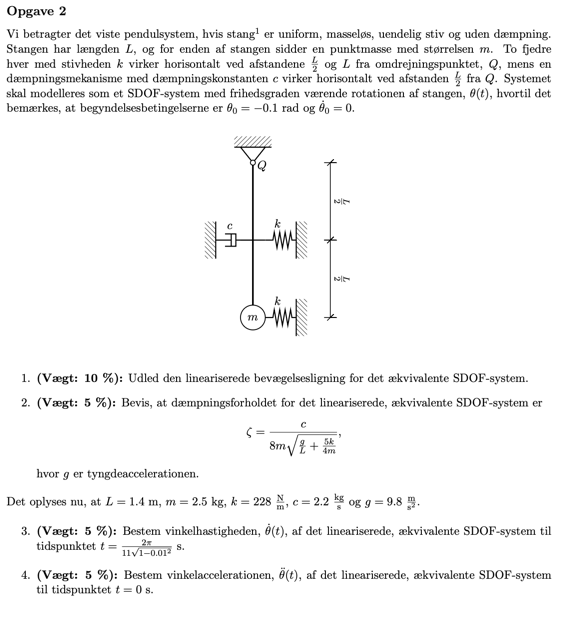

2.1 Vi betragter momentet om understøtningen og får


$$\begin{array}{l}
I_Q \ddot{\theta} =-k\;L\;\sin \left(\theta \right)L\;\cos \left(\theta \right)-k\;\frac{L}{2}\;\sin \left(\theta \right)\;\frac{L}{2}\cos \left(\theta \right)-c\dot{\theta} \;\frac{L}{2}\cos \left(\theta \right)\frac{L}{2}\cos \left(\theta \right)-m\;g\;L\;\sin \left(\theta \right)\\
\;\;\;\;\;\;\;=-\frac{5}{4}k\;\sin \left(\theta \right)\cos \left(\theta \right)L^2 -c\dot{\theta} \frac{L^2 }{4}\cos^2 \left(\theta \right)-m\;g\;L\;\sin \left(\theta \right)
\end{array}$$


Med LTI-antagelsen tager vi $\cos \left(\theta \right)\approx 1,\sin \left(\theta \right)\approx \theta \;$ og får:


$$\;I_Q \ddot{\theta} =-\frac{3}{4}k\;\theta \;L^2 -c\dot{\theta} \frac{L^2 }{4}-m\;g\;L\;\theta$$


Med $I_Q ={m\;L}^2$ får vi (idet vi samtidig dividerer hele udtrykket med $L$):


$$\;\ddot{\theta} +\frac{c}{4m}\;\dot{\theta} +\left(\frac{5k}{4m}\;+\frac{g}{L}\right)\;\theta =0$$


2.2 Fra $\ddot{\theta} +\frac{c}{4m}\;\dot{\theta} +\left(\frac{5k}{4m}\;+\frac{g}{L}\right)\;\theta =0$ kan vi aflæse $\omega_u^2 =\frac{5k}{4m}\;+\frac{g}{L}\;\;\;\Rightarrow \;\;\;\omega_u =\sqrt{\frac{5k}{4m}+\frac{g}{L}}$ . Derudover aflæser vi $2\zeta \omega_u =\frac{c}{4m}\;\;\;\Rightarrow \zeta =\frac{c}{8m\omega_u }$. Altså:


$$\zeta =\frac{c}{8m\sqrt{\frac{5k}{4m}+\frac{g}{L}}}$$


Altså er det vist.

2.3 Fra  $\;\ddot{\theta} +\frac{c}{4m}\;\dot{\theta} +\left(\frac{5k}{4m}\;+\frac{g}{L}\right)\;\theta =0$ kan vi aflæse $m_{\mathrm{eq}} =1,c_{\mathrm{eq}} =\frac{c}{4m},k_{\mathrm{eq}} =\frac{5k}{4m}+\frac{g}{L}$. Således kan vores udtryk skrives som


$$\ddot{\theta} +c_{\mathrm{eq}} \dot{\theta} +k_{\mathrm{eq}} \theta =0$$


Løsningen hertil er


$$\theta \left(t\right)=e^{-\zeta \omega_u t} \left(A_1 \cos \left(\omega_d t\right)+A_2 \sin \left(\omega_d t\right)\right)$$


Vi har endvidere at


$$\omega_d =\omega_u \sqrt{1-\zeta^2 }$$


hvilket regnes i Matlab som:

L = 1.4; %m
m = 2.5; %kg
k = 228; %N/m
c = 2.2; %kg/s
g = 9.8; %m/s^2

zeta = c/(8*m*sqrt(5*k/(4*m)+g/L))

zeta = 0.0100

omega_u = sqrt(5*k/(4*m) + g/L)

omega_u = 11

omega_d = omega_u*sqrt(1-zeta^2)

omega_d = 10.9994

Vores løsning er


$$\theta \left(t\right)=e^{-\zeta \omega_u t} \left(A_1 \cos \left(\omega_d t\right)+A_2 \sin \left(\omega_d t\right)\right)$$


vha. startbetingelserne kan vi finde $A_1$ og $A_2$ i Matlab som:

syms A_1 A_2 t

theta0 = -0.1;
dtheta0 = 0;

theta = exp(-zeta*omega_u*t)*(A_1 * cos(omega_d*t) + A_2 * sin(omega_d * t));
theta_0 = subs(theta, t, 0);

A_1 = round(solve(theta_0 == theta0, A_1), 6)

$$A\_1 = -0.1$$


theta = exp(-zeta*omega_u*t)*(A_1 * cos(omega_d*t) + A_2 * sin(omega_d * t));
dtheta = diff(theta, t);
dtheta_0 = subs(dtheta, t, 0);
A_2 = round(solve(dtheta_0 == dtheta0, A_2), 6)

$$A\_2 = -0.001$$

Således har vi vores løsning


$$\theta \left(t\right)=e^{-0\ldotp 01\cdot 9\ldotp 55t} \left(-0\ldotp 1\cos \left(9\ldotp 55t\right)-0\ldotp 001\sin \left(9\ldotp 55t\right)\right)$$


theta = exp(-zeta*omega_u*t)*(A_1 * cos(omega_d*t) + A_2 * sin(omega_d * t));

Denne kan nu differentieres i Matlab hvorefter vores tidspunkt kan indsættes:

dtheta = diff(theta, t);

t_1 = 2*pi/(11*sqrt(1-0.01^2)); %s

dtheta_t_1 = round(subs(dtheta, t, t_1), 4)

$$dtheta\_t\_1 = 0.0$$

 Altså er hastigheden til det pågældende tidspunkt $\dot{d} \left(\frac{2\pi }{11\sqrt{1-0\ldotp {01}^2 }}\right)=0$ m/s.

2.4Her kan vi blot differentiere vores udtryk igen og indsætte det nye tidspunkt

ddtheta = diff(dtheta,t)

$$ddtheta = \begin{array}{l} \frac{11\,\sigma_{3}\,\left(0.010999449986249311805863726476673\,\sigma_{2}-1.0999449986249311805863726476673\,\sigma_{1}\right)}{50}-\frac{121\,\sigma_{3}\,\left(0.1\,\sigma_{2}+0.001\,\sigma_{1}\right)}{10000}+\sigma_{3}\,\left(12.098789999999998567509695820004\,\sigma_{2}+0.12098789999999998567509695820004\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{6192139857419101\,t}{562949953421312}\right)\\ \sigma_{2}=\cos\left(\frac{6192139857419101\,t}{562949953421312}\right)\\ \sigma_{3}={\mathrm{e}}^{-\frac{11\,t}{100}} \end{array}$$


ddthetha_t_2 = round(subs(ddtheta, t, 0), 4)

$$ddthetha\_t\_2 = 12.1$$

Altså er vores begyndelsesvinkelacceleration $\ddot{d} = 12.1 \, m/s^2$

clear variables; clc; close all;

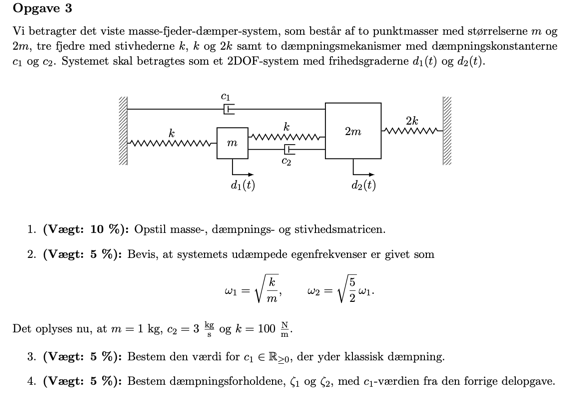

Fra Newtons 2. lov har vi at


$$m\ddot{d_1 } =-{k\;d}_1 +k\left(d_2 -d_1 \right)+c_2 \left(\dot{d_2 } -\dot{d_1 } \right)\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;m\ddot{d_1 } +c_2 \dot{d_1 } -c_2 \dot{d_2 } +2{k\;d}_1 -{k\;d}_2 =0$$



$$2m\ddot{d_2 } =-c_1 \dot{d_2 } -k\left(d_2 -d_1 \right)-c_2 \left(\dot{d_2 } -\dot{d_1 } \right)-2{\mathrm{kd}}_2 \;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;2m\ddot{d_2 } -c_2 \dot{d_1 } +\left(c_1 +c_2 \right)\dot{d_2 } -k\;d_1 +3k\;d_2 =0$$


Hvilket samles til


$$\left\lbrack \begin{array}{cc}
m & 0\\
0 & 2m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c_2  & -c_2 \\
-c_2  & c_1 +c_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2k & -k\\
-k & 3k
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Altså har vi


$$M=\left\lbrack \begin{array}{cc}
m & 0\\
0 & 2m
\end{array}\right\rbrack ,\;\;\;C=\left\lbrack \begin{array}{cc}
c_2  & -c_2 \\
-c_2  & c_1 +c_2 
\end{array}\right\rbrack ,\;\;\;K=\left\lbrack \begin{array}{cc}
2k & -k\\
-k & 3k
\end{array}\right\rbrack$$


3.2 Vores karakteristiske ligning er


$$\det \left(K-\omega^2 M\right)=0$$



$$\det \left(\left\lbrack \begin{array}{cc}
2k-\omega^2 m & -k\\
-k & 2k-\omega^2 2m
\end{array}\right\rbrack \right)=0$$
 

Hvilket vi løser i MatLab som:

syms k omega m c_1 c_2 positive
M = [m 0; 0 2*m];
C = [c_2  -c_2; -c_2   c_1+c_2];
K = [2*k  -k; -k   3*k];

% Karakteritisk ligning: det(K - omega^2 M) = 0
char_eq = det(K - omega^2*M);

disp("Karakteristisk ligning")

Karakteristisk ligning


pretty(char_eq)

   2          2      2  4
5 k  - 7 k m ω  + 2 m  ω




% Solve for omega
omega_sol = solve(char_eq == 0, omega)

$$omega\_sol = \left(\begin{array}{c} \frac{\sqrt{k}}{\sqrt{m}}\\ \frac{\sqrt{10}\,\sqrt{k}}{2\,\sqrt{m}} \end{array}\right)$$

Altså er det vist.

3.3 For klassisk dæmpning kræver vi at $\tilde{C}$ er diagonal, hvor


$$\tilde{C} =\Phi^T C\Phi$$


Idet $\Phi$ er modalmatricen. Denne findes I Matlab ved at løse egenvektoproblemet


$$\left(K-{\omega_j }^2 M\right)\phi_j =0$$


for hver af vores egenværdier. Dette gøres I Matlab som

[Phi, Lambda] = eig(M\K)

$$Phi = \left(\begin{array}{cc} 1 & -2\\ 1 & 1 \end{array}\right)$$

$$Lambda = \left(\begin{array}{cc} \frac{k}{m} & 0\\ 0 & \frac{5\,k}{2\,m} \end{array}\right)$$


omega_j = sqrt(diag(Lambda))

$$omega\_j = \left(\begin{array}{c} \frac{\sqrt{k}}{\sqrt{m}}\\ \frac{\sqrt{2}\,\sqrt{5}\,\sqrt{k}}{2\,\sqrt{m}} \end{array}\right)$$

Altså er vores modalmatrice


$$\Phi =\left\lbrack \begin{array}{cc}
1 & -2\\
1 & 1
\end{array}\right\rbrack$$


Således får vi at


$$\Phi^T \left\lbrack \begin{array}{cc}
c_2  & -c_2 \\
-c_2  & c_1 +c_2 
\end{array}\right\rbrack \Phi =\left\lbrack \begin{array}{cc}
1 & 1\\
-2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
3 & -3\\
-3 & c_1 +3
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & -2\\
1 & 1
\end{array}\right\rbrack$$


C_tilde = Phi' * subs(C, c_2, 3) * Phi

$$C\_tilde = \left(\begin{array}{cc} c_{1} & c_{1}\\ c_{1} & c_{1}+27 \end{array}\right)$$

Altså får vi vores modale dæmpningsmatrice


$$\tilde{C} =\left\lbrack \begin{array}{cc}
c_1  & c_1 \\
c_1  & c_1 +27
\end{array}\right\rbrack$$


som kun er diagonal for $c_1 = 0$, hvorfor $c_1 = 0$ for klassisk dæmpning.

3.4 Vi har at dæmpningsforholdet er givet som


$$\zeta_j =\frac{\tilde{c_{\mathrm{jj}} } }{2\tilde{m_{\mathrm{jj}} } \omega_j }$$


Altså

m_num = 1;
k_num = 100;


omega_j_num = subs(omega_j, [k, m], [k_num, m_num]);
M_num = subs(M, m, m_num);
M_tilde = Phi'*M_num*Phi

$$M\_tilde = \left(\begin{array}{cc} 3 & 0\\ 0 & 6 \end{array}\right)$$

C_tilde = [0    0; 0    27]

C_tilde =      0     0
     0    27



zeta_1 = round(C_tilde(1,1)/(2*M_tilde(1,1)*omega_j_num(1)), 4)

$$zeta\_1 = 0$$

zeta_2 = round(C_tilde(2,2)/(2*M_tilde(2,2)*omega_j_num(2)), 4)

$$zeta\_2 = 0.1423$$

Således får vi de to dæmpningskonstanter $\zeta_1 =0,\;\zeta_2 =0\ldotp 1423$.

clear variables; clc; close all;

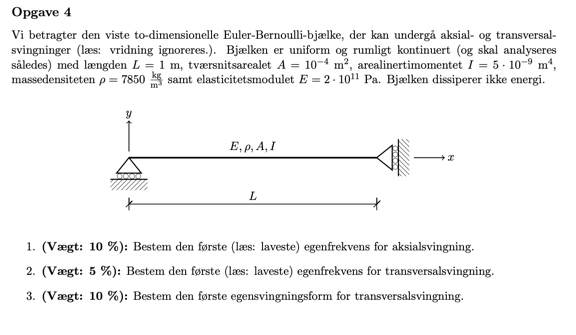

4.1 For aksialsvingningen har vi randbetingelserne


$$\frac{d\varphi_x }{x}\left(0,t\right)=0\;\;\;\Rightarrow \;\frac{d\phi_j^x }{x}\left(0\right)=0$$



$$\varphi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\;\phi_j^x \left(L\right)=0$$


Og den generelle løsning


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\frac{\omega_j }{\eta }x\right)+A_j^{\left(2\right)} \sin \left(\frac{\omega_j }{\eta }x\right)$$


Fra $\frac{d\varphi_x }{x}\left(0,t\right)=0\;\;\;\Rightarrow \;\frac{d\phi_j^x }{x}\left(0\right)=0$ har vi at


$$A_j^{\left(2\right)} =0$$


Så


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\frac{\omega_j }{\eta }x\right)$$


Fra $\;\phi_j^x \left(L\right)=0$ har vi at


$$\frac{\omega_j }{\eta \;}L=\pi \;j-\frac{\pi }{2}$$


Altså


$$\omega_j =\frac{\left(\pi \;j-\frac{\pi }{2}\right)\eta }{L}=\frac{\left(\pi \;j-\frac{\pi }{2}\right)}{L}\sqrt{\frac{E}{\rho }}$$


Den laveste vinkelegenfrekvens er for $j = 1$ så

L = 1; %m
E = 2e11; %Pa
rho = 7850; %kg/m^3

omega_1 = (pi/2)/L * sqrt(E/rho)

omega_1 = 7.9287e+03

Altså er den laveste egenfrekvens for aksialsvinging $\omega_1 \approx 7929$ rad/s. 

4.2 For transversalsvinging er fritlegemebevægelse ikke hindret, hvorfor den laveste "egensvingningsform" her er fritlegemebevægelsen, hvor $\omega_1 = 0$.

4.3 Den venstre understøtning forhindrer transversal bevægelse


$$\varphi_y \left(0,t\right)=0\;\;\;\Rightarrow \;\;\phi_j^y \left(0\right)=0$$


Ingen af de to understøtning forhindrer  et moment for transversalsvingning således at


$$\frac{d^2 \varphi_y \left(0,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0$$



$$\frac{d^2 \varphi_y \left(L,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


Den højre understøtning fungerer som en fri ende for transversalsvining således at forskydningskraften $V=0$ her. Altså


$$\frac{d^3 \;\varphi_y \left(L,t\right)}{x^3 }=0\;\;\;\Rightarrow \frac{d^3 \phi_j^y \left(L\right)}{x^3 }=0$$


Den generelle løsning for transversalsvingning er


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\epsilon_j x\right)+A_j^{\left(2\right)} \sin \left(\epsilon_j x\right)+A_j^{\left(3\right)} \cosh \left(\epsilon_j x\right)+A_j^{\left(4\right)} \sinh \left(\epsilon_j x\right)$$


Da $\omega_1 = 0$ har vi $\epsilon_j = 0$, hvorved:


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} +A_j^{\left(3\right)}$$


Fra $\phi_j^y \left(0\right)=0$ har vi


$$\phi_j^y \left(0\right)=A_j^{\left(1\right)} +A_j^3 =0\;\;\;\Rightarrow A_j^{\left(1\right)} =-A_j^3$$


Den første egensvingningsform for transversalbevægelse er da


$$\phi_1^y \left(x\right)=0$$
